# Seminar 3

## PROBLEM 12

Data in Table 6 (also in file SM22_Seminar_3_Fish.xlsx) corresponds to an experiment carried out to compare 3 different methods to cook fish. For that purpose, 36 fish samples were randomly split in 3 groups of 12 samples. Samples in each group were cooked according to one of the methods, which we will call A, B, and C.

To compare the 3 methods, judges were asked to taste the cooked f fish samples and rate them in terms of 4 variables: Aroma, Flavor, Texture and Moisture. Table 6 provides these rates.

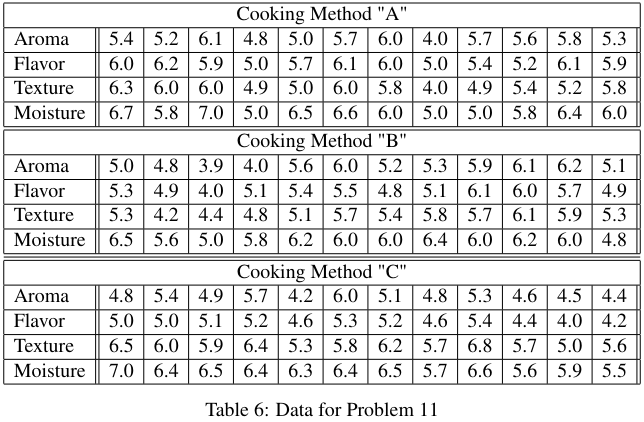

### a) State the null and alternative hypotheses required for the comparison indicated above.

$\begin{cases}
      H_{0}: \mathbf{\tau_{l}} = \mathbf{\tau_{l\prime}} = \mathbf{0} \quad \forall l, l\prime \in \{A, B, C\}\\
      H_{A}: \exists l \neq l\prime \quad \text{such that} \quad \mathbf{\tau_{l}} \neq \mathbf{\tau_{l\prime}}\\
\end{cases}$ where $\mathbf{\tau_{l}}$represents the treatment effect of population $l$.

### b) Indicate what method would you use to test the hypotheses stated in (a). Indicate what assumptions would be needed in order for your method to be valid. For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

I would use MANOVA. The assumptions are the following:

For each population $l$: $\mathbf{X}_{l,1}, \mathbf{X}_{l,2}, ..., \mathbf{X}_{l,n_{l}} \quad \forall l \in \{1, g\}$

- $\mathbf{X}_{l,1}, \mathbf{X}_{l,2}, ..., \mathbf{X}_{l,n_{l}} \quad \forall l \in \{1, g\}$ is a random sample of size $n_l$ from a population with mean $\mathbf{\mu_{l}}$. The random samples from different populations are independent.

- All populations have a common covariance matrix $\mathbf{\Sigma}$.

- All populations are multivariate normal or the sample size is large enough.

### c) Test the hypotheses stated in (a) at significance level α = 0.05. Provide all the relevant numerical details and clearly state your conclusion (both in terms of the null and in plain language).

alpha = 0.05;

% Importing table
filename = 'semi3/SM22_Seminar_3_Fish.xlsx';
% check that working directory is ME-2024
raw = readtable(filename, 'ReadVariableNames', false);
raw = strrep(raw{:,:}, ',', '.');

% Fill the input matrix
p = 4;
g = 3;
X = zeros(12, p, g); % n_l, p, g
X(:, :, 1) = str2double(raw(1:4, 3:14)');
X(:, :, 2) = str2double(raw(5:8, 3:14)');
X(:, :, 3) = str2double(raw(9:12, 3:14)');

% Compute the MANOVA table (treatment or between matrix B and residual or within matrix W)
X_bar = squeeze(mean(X, 1)); % p 4x3
n = size(X, 2);

% Compute Between Sum of squares and cross-products
x_bar = mean(X_bar, 'all'); % x_bar is the overall sample mean now
pop_wise_x_bar = mean(X_bar, 2);
df_B = g-1;
% SSP_B = zeros(p, p);
% for l=1:g
%     SSP_B = SSP_B + n * (pop_wise_x_bar(l) - x_bar)' * (pop_wise_x_bar(l) - x_bar);
% end
% SSP_B
SSP_B = n * (pop_wise_x_bar - x_bar) * (pop_wise_x_bar - x_bar)'

SSP_B =     0.3924    0.2914   -0.0426   -0.6412
    0.2914    0.2165   -0.0317   -0.4763
   -0.0426   -0.0317    0.0046    0.0697
   -0.6412   -0.4763    0.0697    1.0478


% Compute Within Sum of squares and cross-products
df_W = g*(n-1);
SSP_W = zeros(p, p);
for l=1:g
    SSP_W = SSP_W + n * (X(:,:,l) - pop_wise_x_bar')' * (X(:,:,l) - pop_wise_x_bar'); % very similar but with individual population means
end
SSP_W

SSP_W =    57.8356   40.3711   29.1978   20.4156
   40.3711   52.6522   21.8656   21.5811
   29.1978   21.8656   55.9589   33.6878
   20.4156   21.5811   33.6878   45.5056


wilks_lambda = det(SSP_W) / det(SSP_B + SSP_W)

wilks_lambda = 0.9464

F_hat= wilks2f(wilks_lambda, p, df_B, df_W)

F_hat = 0.0419

F_crit = F_critical(alpha, p, df_B, df_W)

F_crit = 2.8486

function [s, df_1, df_2] = get_DoF_fisher(p, df_num, df_denom)
    % Get the Degrees of Freedom for the Fisher distribution depending on
    % the amount of variables (dimensions).
    % Notice that this formula is simplified a lot when p=1 (univariate)
    % df_1 = df_num
    % df_2 = df_denom
    s = min(p, df_num);
    df_1 = p * df_num;
    df_2 = s * (df_denom - (p-df_num+1)/2) - p*df_num/2 + 1;
end

function F_hat = wilks2f(wilks_lambda, p, df_num, df_denom)
    % Convert from from Wilk's Lambda distribution to F-distribution
    [s, df_1, df_2] = get_DoF_fisher(p, df_num, df_denom);
    F_hat = ( (1 - nthroot(wilks_lambda, s)) / df_1 ) / ( nthroot(wilks_lambda, s) / df_2 );
end

function F_crit = F_critical(alpha, p, df_num, df_denom)
    % Get the critical Fisher distribution value at significance level
    % 1-alpha for p variables (univariate=1, multivariate>1). df_num can be
    % the Degrees of Freedom of the Between matrix, the DoF of interaction in
    % two-way MANOVA, as well as the factors
    [~, df_1, df_2] = get_DoF_fisher(p, df_num, df_denom);
    F_crit = finv(1-alpha, df_1, df_2);
end

Since the estimator of the F-distribution exceeds the critical value we can reject the null hypothesis, that is, we can say that exists a combination of $l, l\prime$ such that $\mathbf{\mu_{l}} \neq \mathbf{\mu_{l\prime}}$.

### d) Compute 95% confidence regions for the average rating differences between the 3 cooking methods. These regions must hold at the specified confidence level simultaneously (e.g. do not forget to correct the significance level for multiple comparisons).

% Post-hoc multivariate test
T2_hat = zeros(g*(g-1)/2, 1);
m = 0;
for i=1:g
    for j=i+1:g
        m = m+1;
        T2_hat(m) = (X_bar(:, i) - X_bar(:, j))' / ((1/n(i) + 1/n(j)) * SSP_W / df_W) * (X_bar(:, i) - X_bar(:, j));
    end
end

Index exceeds the number of array elements. Index must not exceed 1.


% m = g*(g-1) / 2; % correction
F_crit_post_hoc = df_W * p / (df_W-p+1) * finv((1-alpha)/m, p, df_W-p+1)
x_bar = mean(X_bar, 2)'; % now x_bar is the feature-wise mean
CI_multivariate(x_bar, SSP_W, F_crit_post_hoc)
function ci = CI_multivariate(x_bar, cov_mat, c2)
    ci = [x_bar' - sqrt(c2 * diag(cov_mat)), x_bar' + sqrt(c2 * diag(cov_mat))];
end

## PROBLEM 13

File *SM22_Seminar_3_Diet.xlsx* contains data from a study aimed to compare the effect of 3 different diets from a sample of 76 individuals. Each row of the file corresponds to one individual, and provides the gender, the type of diet (from 1 to 3) and two measurements of weight: one before starting the diet and another one after 6 weeks of diet. For the purpose of this problem we will assume that the data is suitable for analysis under a 2-way factorial ANOVA (i.e. the data fulfills all the assumptions required for such model), and we will use significance level α = 0.05:

### a) Test whether there is a significant interaction between (type of diet) and (gender). Clearly state:

- The corresponding null and alternative hypotheses: $\begin{cases}
      H_{0}: \gamma_{11} = {\gamma_{12} = ... = \gamma_{gb} = 0\\
      H_{A}: \text{At least one } \gamma_{lk} \neq 0\\
\end{cases}$ where $\gamma_{\mathrm{lk}}$ is the interaction between factor 1 and factor 2 for factor levels $l$ and $k$.

- Your conclusion: We cannot reject $H_0$

- The relevant numerical details

% Importing table
filename = 'semi3/SM22_Seminar_3_Diet.xlsx';
% check that working directory is ME-2024
raw = readtable(filename); % assuming that gender 0=female, 1=male

% ANOVA parameters
alpha = 0.05;
n = sum(raw{:,'gender'} == 0 & raw{:,'Diet'} == 1); % page 312: assume n independent observations can be observed at each of the gb combinations
g = 2; % g levels of factor 1
b = 3; % b levels of factor 2

% Load data into input matrix X
X = raw{:, 'weightBeforeDiet'} - raw{:, 'weightAfterDiet'};
X = reshape(X, [], b, g);
X_bar = squeeze(mean(X, 1)); % diets x genders

% Performing two-way factorial ANOVA
df_f1 = g-1;
SS_f1 = b * n * sum((mean(X_bar, 1) - mean(X_bar, 'all')).^2)

SS_f1 = 0.2335

df_f2 = b-1;
SS_f2 = g * n * sum((mean(X_bar, 2) - mean(X_bar, 'all')).^2)

SS_f2 = 44.4619

df_int = (g-1)*(b-1);
SS_int = n * sum((X_bar - mean(X_bar, 1) - mean(X_bar, 2) + mean(X_bar, 'all')).^2, 'all')

SS_int = 27.7186

df_res = g*b*(n-1);
% shiftdim is to make the subtraction viable, to subtract using 
% broadcasting, the first dimensions have to be compatible
% (e.g.: X is 12x3x2 and not subtractible with X_bar' which is 
% 3x2, by using shiftdim we make shiftdim(X, 1) be 3x2x12 which now works
% basically we are subtracting x_bar to all samples
SS_res = sum((shiftdim(X, 1) - X_bar).^2, 'all')

SS_res = 343.9025

% To test the hypothesis we can use Wilk's Lambda distribution and
% convert to Fisher's distribution (page 316)
wilks_lambda = SS_res / (SS_int + SS_res);
F_hat = wilks2f(wilks_lambda, 1, df_int, df_res)

F_hat = 2.6598

% Or we can calculate the F-ratios of the mean squares directly (page 315)
MS_int = SS_int / df_int;
MS_res = SS_res / df_res;
F_hat = MS_int / MS_res

F_hat = 2.6598

F_crit = F_critical(alpha, 1, df_int, df_res)

F_crit = 3.1359

### b) Based on your results from (a), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

SInce we have found that there is no evidence of interaction between variables, further analysis of this data will be based on assessing main effects.

### c) Proceed to analyze main or simple effects, according to your answer in (b). In all cases provide your conclusions, clearly indicating what they imply stated in plain language.

$\begin{cases}
      H_{0}: \tau_{1} = {\tau_{2} = ... = \tau_{g} = 0\\
      H_{A}: \text{At least one } \tau_{l} \neq 0\\
\end{cases}$ where $\tau_l$ is the fixed effect of factor 1.

% Check main effects for factor 1
wilks_lambda = SS_res / (SS_f1 + SS_res);
F_hat = wilks2f(wilks_lambda, 1, df_f1, df_res)

F_hat = 0.0448

F_crit = F_critical(alpha, 1, df_f1, df_res)

F_crit = 3.9863

We cannot conclude that there are significant main effects regarding the first factor since F_hat < F_crit.

$\begin{cases}
      H_{0}: \beta_{1} = {\beta_{2} = ... = \beta_{b} = 0\\
      H_{A}: \text{At least one } \beta_{k} \neq 0\\
\end{cases}$where $\beta_k$ is the fixed effect of factor 2.

% Check main effects for factor 2
wilks_lambda = SS_res / (SS_f2 + SS_res);
F_hat = wilks2f(wilks_lambda, 1, df_f2, df_res)

F_hat = 4.2665

F_crit = F_critical(alpha, 1, df_f2, df_res)

F_crit = 3.1359

We can conclude that there are significant main effects regarding the second factor since F_hat > F_crit.

### d) For any significant effect identified in (c), provide the corresponding confidence interval (keep in mind that, even though you are testing just a few selected intervals, you must correct the significance level for all possible multiple comparisons).

m = b*(b-1)/2;
c = tinv(1-alpha/(p*2*m), df_res) * sqrt(2*SS_res/(df_res*g*n))

c = 1.9561

CIs = zeros(m, 2);
temp = 1

temp = 1

for i=1:b
    for j=i+1:b
        av = (mean(X_bar(i, :)) - mean(X_bar(j, :)));
        CIs(temp, :) = [av - c, av + c];
        temp = temp+1;
    end
end
CIs

CIs =    -2.1270    1.7853
   -3.7020    0.2103
   -3.5311    0.3811


## PROBLEM 14

In one experiment involving remote sensing, the spectral reflectance of three species of 1-year-old seedlings was measured at various wavelengths during the growing season. The species of seedlings used were sitka spruce (SS), Japanese larch (JL), and lodgepole pine (LP). Files SM22_Seminar_3_Remote_??.xslx provides two of the variables that were measured:

- X1 = percent of spectral reflectance at wavelengt 560 nm (green)

- X2 = percent of spectral reflectance at wavelength 720 nm (near infrared)

where ?? are replaced by the abbreviations provided above for the 3 species of seedlings (SS, JL and LP).

### a) Test whether the mean reflectance (bi-dimensional, in terms of the two provided variables) is different between the 3 species of seedlings (at significance level α = 0.05). For the purpose of this question, consider that any required assumptions are met (no need to assert them).

% Importing table
filename1 = 'semi3/SM22_Seminar_3_Remote_SS.xlsx';
filename2 = 'semi3/SM22_Seminar_3_Remote_JL.xlsx';
filename3 = 'semi3/SM22_Seminar_3_Remote_LP.xlsx';
% check that working directory is ME-2024

% Load data into input matrix
raw = readtable(filename1);
SS = raw{:,:};
raw = readtable(filename2);
JL = raw{:,:};
raw = readtable(filename3);
LP = raw{:,:};
n = [size(SS, 1), size(JL, 1), size(LP, 1)];
cum_n = cumsum(n)

cum_n =     45    80   140


p=2;
g=3;

% MANOVA
X = [SS' JL' LP']';
x_bar = mean(X, 1)

x_bar =    11.2797   30.4815


df_B = g-1;
SSP_B = zeros(p, p);
prev_idx = 1

prev_idx = 1

for l=1:g
    x_bar_pop_wise = mean(X(prev_idx:n(l), :), 1)
    SSP_B = SSP_B + n * (x_bar_pop_wise - x_bar)' * (x_bar_pop_wise - x_bar);
end

x_bar_pop_wise =     8.1778   28.7669


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

### b1) In case you find a significant difference in (a), test what groups differ.

### b2) In case you do not find a significant difference in (a), construct confidence intervals for each pair of groups along each dimension. The intervals should simultaneously guarantee a FWER (family-wise error rate) of α = 0.05

### c) Assess whether the data fulfills the required assumptions for the test methodology that you applied in (a). Based on this, indicate whether you believe your results can be considered valid or not (justify).

## PROBLEM 15

In this problem we will analyze continuous evaluation data that corresponds to Statistical Models from 2019 to 2021. To this end, file SM_SamplesMarks_2019_2021.xlsx contains data from 78 students. For each of them (corresponding to a row in the referenced file), we have collected:

- The year in which the student took the course.

- The marks obtained in each of the 5 labs with deliverables.

- The resulting Continuous Evaluation mark (which is simply the average of the lab marks).

- The result of the student in the final exam, as a binary variable (1 = pass).

Students included in the file were selected randomly according to the following criteria:

- For each year, 13 students who passed the exam and 13 students who did not pass de exam were selected.

- Students with a Continuous Evaluation mark below 5.0 were not eligible, since they could not take the final exam.

We wish to assess whether, on average, there is a difference in the Continuous Evaluation mark of students depending on:

- Whether they successfully passed the final exam or not.

- The year in which they took the course. (This question is important because, in our case, the subject has both been updated every year and has changed some of its teachers)

Because we are using the same dataset for the 3 problems of this lab, we will set our significance level for each problem to α = 0.017, which is approximately 0.05/3.

### a) Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

Independence of the observations, Multivariate normality, Sphericity (sometimes called circularity) (that the variances of the differences for all pairs of repeated measures be equal)

### b) Test whether there is a significant interaction effect. Clearly state: 

- The corresponding null and alternative hypotheses

- Your conclusion

- The relevant numerical details

### c) Based on your results from (b), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

### d) Proceed to analyze main (In case of analyzing main effects, make sure to provide a complete analysis, e.g. including any post-hoc tests that might be necessary to determine what groups differ, if any) or simple effects, according to your answer in (c). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.

## PROBLEM 16

Using data from Problem 15, we wish to assess whether, on average, there is a difference considering all the 5 Lab Marks of students (not simply their mean), depending on:

- Whether they passed the final exam or not.

- The year in which they took the course.

Because we are using the same dataset for the 3 problems of this lab, we will set our significance level for each problem to α = 0.017, which is approximately 0.05/3.

### a) Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

b) Test whether there is a significant interaction effect. Clearly state:

- The corresponding null and alternative hypotheses

- Your conclusion

- The relevant numerical details

### c) Based on your results from (a), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

### d) Proceed to analyze main (In case of analyzing main effects, make sure to provide a complete analysis, e.g. including any post-hoc tests that might be necessary to determine what groups differ, if any) or simple effects, according to your answer in (b). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.